## Пример как получить ноту

clear all
close all

load('const.mat')   % Load consts as NFFT, ds, NOTES...
load('data.mat')    % Load data object with 1-noise, 2-85 notes

Выбираем конкретную ноту и длительность

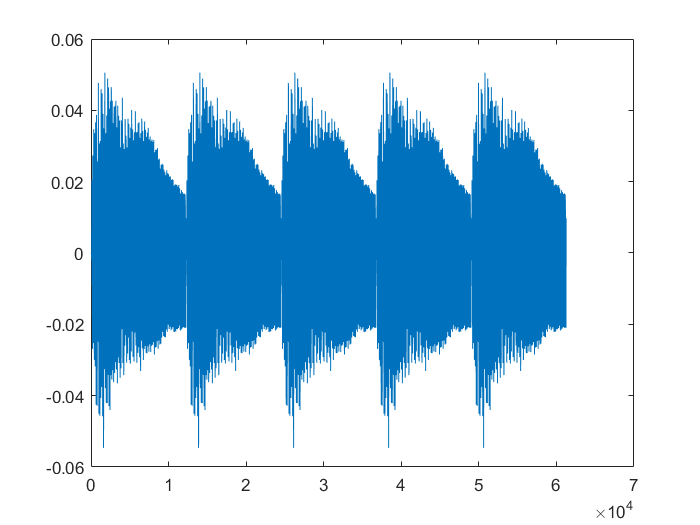

octave = 3;
note = 7;
dur = 1/4;
bpm = 216;

t_dur = dur*4/(bpm/60);
t_sampl = floor(Fs*t_dur);
ind = octave*12 + note + 1;
sig_note = data(1:t_sampl, ind);

sig_note = repmat(sig_note, [1 5]);
sig_note = reshape(sig_note, [1 5*t_sampl]);

plot(sig_note)


sound(sig_note, Fs)

## Выбираю мелодию и создаю ее сигналами

## Mario in proper order

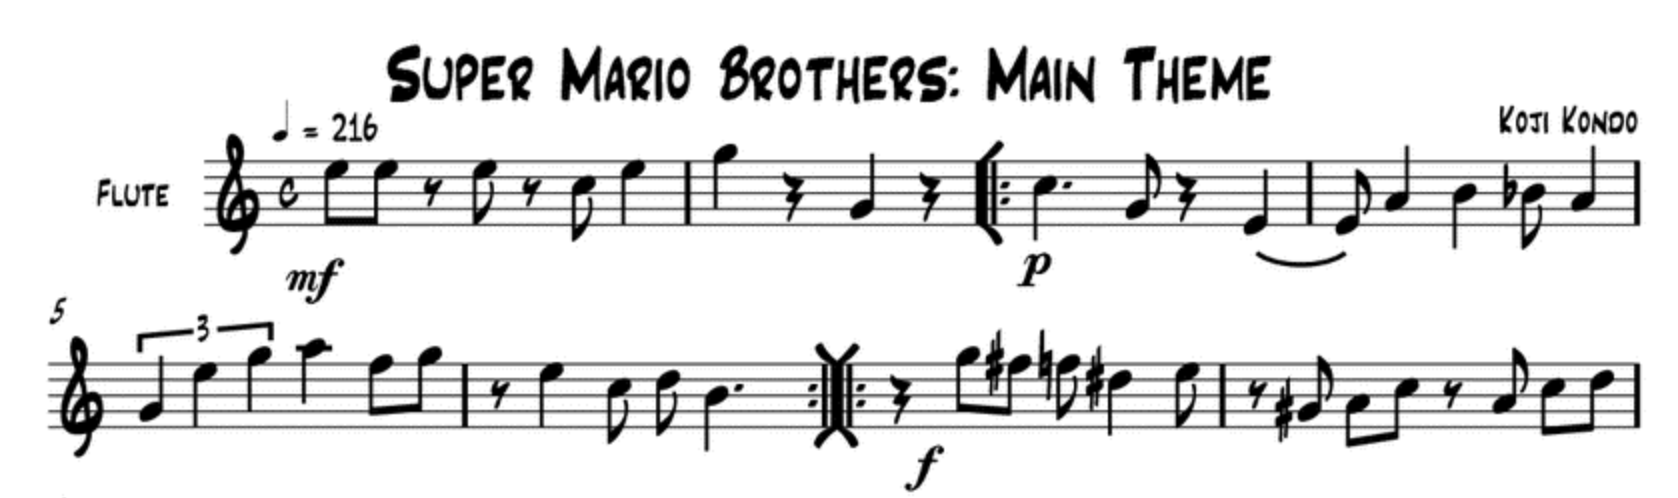

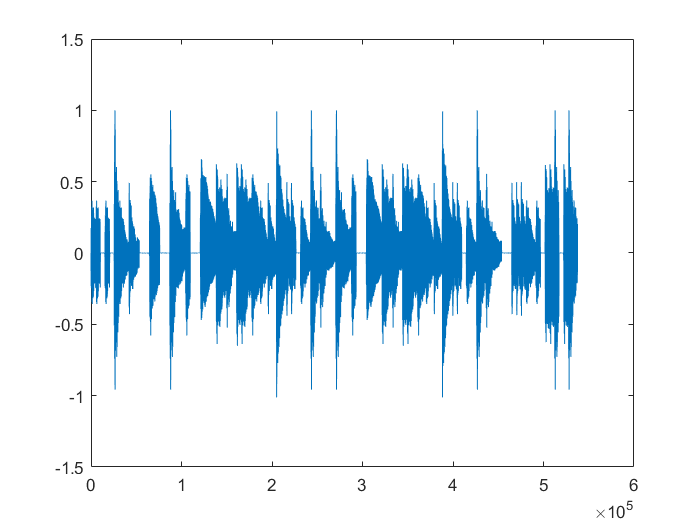

% Правильный пордок нот
note_list = ["C", "C#", "D", "D#", "E", "F", "F#", "G", "G#", "A", "A#", "B"];

% Последовательность нот в композиции
notes = ["E4", "1/8";
         "E4", "1/8";
         "0",  "1/8";
         "E4", "1/8";
         "0",  "1/8";
         "C4", "1/8";
         "E4", "1/4";
         
         "G4", "1/4";
         "0",  "1/4";
         "G3", "1/4";
         "0",  "1/4";
         
         "C4", "3/8";
         "G3", "1/8";
         "0",  "1/4";
         "E3", "3/8";
         
         "A3", "1/4";
         "B3", "1/4";
         "A#3","1/8";
         "A3", "1/4";
         
         "G3", "1/5";
         "E4", "1/5";
         "G4", "1/5";
         "A4", "1/4";
         "F4", "1/8";
         "G4", "1/8";
         
         "0",  "1/8";
         "E4", "1/4";
         "C4", "1/8";
         "D4", "1/8";
         "B3", "3/8";
         
         "C4", "3/8";
         "G3", "1/8";
         "0",  "1/4";
         "E3", "3/8";
         
         "A3", "1/4";
         "B3", "1/4";
         "A#3","1/8";
         "A3", "1/4";
         
         "G3", "1/5";
         "E4", "1/5";
         "G4", "1/5";
         "A4", "1/4";
         "F4", "1/8";
         "G4", "1/8";
         
         "0",  "1/8";
         "E4", "1/4";
         "C4", "1/8";
         "D4", "1/8";
         "B3", "3/8";
         
         "0",  "1/4";
         "G4", "1/8";
         "F#4","1/8";
         "F4", "1/8";
         "D#4","1/4";
         "E4", "1/8";
         
         "0",  "1/8";
         "G#3","1/8";
         "A3", "1/8";
         "C4", "1/8";
         "0",  "1/8";
         "A3", "1/8";
         "C4", "1/8";
         "D4", "1/8"];
tact_cnt = 12;          % There is 12 tacts in melody
time_tact = 2;          % 1 tact has 2 seconds

seq = [];           % Сигналы реальных нот
Yreal_notes = [];   % Метки (label) реальных нот ( (N/2)*tact_cnt*time_tact )

for i = 1:length(notes)
    
    % Define duration
    t_temp = str2num(notes(i,2));
    t_temp = floor(Fs*t_temp*4/(bpm/60));
    
    % Make time dividable to NFFT = 1024. Bad trick, but i need it
    a = floor(t_temp/1024);
    t_temp = a*1024;
    
    % Define the note
    if notes(i, 1) == '0'
        ind = 1;
        s = data(1:t_temp, ind);
    else
        c = char(notes(i, 1));      % Get 'E#5'
        num = str2num(c(end));      % Take 5
        c = c(1:end-1);             % Take 'E#'
        
        ind = find(note_list==c);   % Take linear index of note
        ind = num*12 + ind + 1;     % Take total index for 'data' matrix
        
        s = data(1:t_temp, ind);
    end
    
    seq = cat(2,seq,s');
    
    ny = floor(t_temp/NFFT);
    Yreal_notes = cat(2, Yreal_notes, ind*ones(1, ny));
    
end

seq = seq ./ max(seq);

seq = seq + 10e-5*rand(1, length(seq));    % Добавил шум (иначе в спектре NaN)

figure
plot(seq)

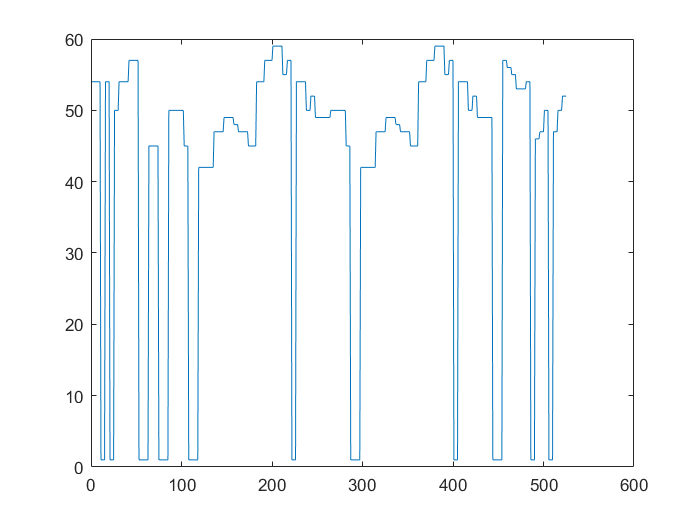


figure
plot(Yreal_notes)


sound(seq, Fs)

audiowrite('My_mario.wav', seq, Fs)

save('Yreal_notes.mat', 'Yreal_notes')